# Figure 2: Fitting to the Den-Haan Experiment

uses data files dat2_litParams_fullCellulose_NGAM.mat and ivd.mat

%Generate/load the data
overwritefiles = true;
%overwritefiles = false;
dat2 = dat2_litParams;
dat2.logalpha = log2(dat2.alpha);
dat2.log10alpha = log10(dat2.alpha);


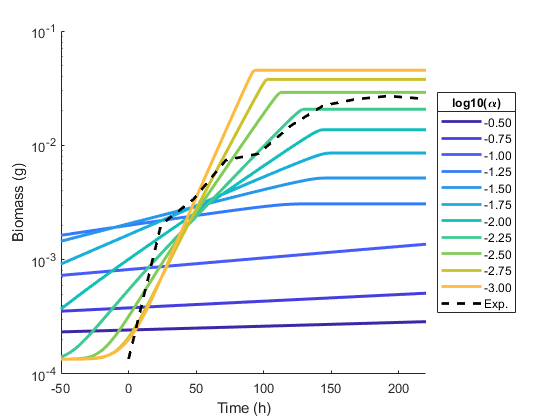

maxtime = 220;

%plot the series adjusted for lag phases
%Version 1: move the sim data

if ~isfield(dat2,'shift_hours')
    steplength = dat2.t{1}(2);
    dat2.shift_hours = dat2.shift * steplength;
end

% %Pare down the data
fig2dat = dat2;
% % 
% % % Attempt 1: get a bunch of alphas around the best A
% % n_pre = 4; %number of values on each side
% % n_post = 4;
% % fig2dat = dat2(bestrow-n_pre:bestrow+n_post,:);
% 
%Attempt 2: manual selection
bestrow = find(dat2.alpha == besta);
%keepas = unique([-1 -1.5 -2 -2.5 -3 -3.5 -4 -4.5 dat2.log10alpha(bestrow)]);
keepas = -1:-.25:-4;
keepas = -1:-.5:-4;
keepas = -.5:-.25:-3;
%keepas = dat2.log10alpha;
fig2dat = dat2(ismember(dat2.log10alpha,keepas),:);

f = figure();
hold on;
[nrows,ncols] = size(fig2dat);
colors = parula(2 + nrows);
for i = 1:nrows
    r = fig2dat(i,:);
    steplength = r.t{1}(2);
    t_extend = [(-xmax:steplength:-1)'; r.t{1}];
    t_shifted = t_extend + r.shift_hours;
    bio_extend = [repmat(r.biomass{1}(1),length(t_extend) - length(r.t{1}),1); r.biomass{1}];
    %startpos = find(t_shifted == 0);
    %endpos = find(t_shifted == xmax);
    %plot(t_shifted(startpos:endpos),bio_extend(startpos:endpos),'color',colors(i,:),'lineWidth',2);
    plot(t_shifted,bio_extend,'color',colors(i,:),'lineWidth',2);
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--k','linewidth',2);
alphas_log10 = fig2dat.log10alpha;
expphrase = 'Exp.       ';
alphaphrases = num2str(round(alphas_log10,3),'%1.2f');
[~,phrasesize] = size(alphaphrases);
expphrase = expphrase(1:phrasesize);
leg = legend([alphaphrases;expphrase],'location','eastoutside');
title(leg,'log10(\alpha)');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');
xlim([-50,maxtime]);

%title('Biomass comparison (lag shift:Sim moved to IV)');
hold off;

if overwritefiles
    savefig(f,'.\figs\Fig2.fig','compact');
    saveas(f,'.\figs\Fig2.png');
    saveas(f,'.\figs\Fig2.eps');%for LaTeX
end